gyro = readtable('Lf')

gyro = 10×5 table
    Larmor_max_Mhz_    Larmor_min_Mhz_    Ho_kG_res0_01     Per         Var5     
    _______________    _______________    _____________    _____    _____________

        15.412             15.411             3.63             8    {0×0 char   }
        15.414             15.412             3.63             4    {0×0 char   }
        15.414             15.412             3.63             2    {0×0 char   }
        15.414             15.412             3.63             1    {0×0 char   }
        15.414             15.412             3.63           0.5    {0×0 char   }
        15.413             15.411             3.63          0.25    {0×0 char   }
        15.413             15.411             3.63         0.125    {0×0 char   }
        15.413              15.41             3.63             0    {0×0 

larmor_max = gyro.Larmor_max_Mhz_;
larmor_min = gyro.Larmor_min_Mhz_;
larmor = ((larmor_max+larmor_min)/2)*1e6;
Mag = gyro.Ho_kG_res0_01*1e3;
gyro = larmor./Mag*2*pi

gyro = 	1.0e+04 *

    2.6676
    2.6678
    2.6678
    2.6678
    2.6678
    2.6677
    2.6676
    2.6676
    2.6676
    2.6676


mean(gyro)

ans = 2.6677e+04

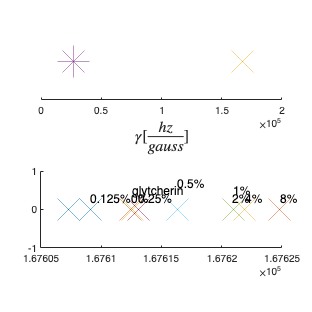

figure;
subplot(2,1,1)
set(gcf,'position',[0,0,1000,1000])
scatter (2*pi*gyro,0,1000,'x');
hold on
scatter (2*pi*4257.608,0,1000,'*');

ax = gca;
ax.YAxis.Visible = 'off';
xlabel(ax,'$\gamma[\frac{hz}{gauss}]$',Interpreter='latex',FontSize=16)



subplot(2,1,2)


set(gcf,'position',[0,0,1000,1000])
scatter (2*pi*gyro,0,1000,'x');
text(2*pi*gyro(2),0.3,'8%',FontSize=12)
text(2*pi*gyro(3),0.3,'4%',FontSize=12)
text(2*pi*gyro(4)-0.15,0.3,'2%',FontSize=12)
text(2*pi*gyro(5),0.5,'1%',FontSize=12)
text(2*pi*gyro(6),0.7,'0.5%',FontSize=12)
text(2*pi*gyro(7),0.3,'0.25%',FontSize=12)
text(2*pi*gyro(8)-0.1,0.3,'0.125%',FontSize=12)
text(2*pi*gyro(9),0.3,'0%',FontSize=12)
text(2*pi*gyro(10),0.5,'glytcherin',FontSize=12)

text(2*pi*gyro(11),0.7,'unknown',FontSize=12)

Index exceeds the number of array elements. Index must not exceed 10.

hold on
scatter (2*pi*mean(gyro),0,1000,'x');
text(2*pi*mean(gyro(2:11, 1)),0.9,'$Average=2.67\cdot10^4$',FontSize=16,Interpreter='latex')
2*pi*mean(gyro(2:11, 1))
ax = gca;
ax.YAxis.Visible = 'off';
xlabel(ax,'$\gamma[\frac{hz}{gauss}]$',Interpreter='latex',FontSize=16)

annotation("textarrow",[0.695 0.8325],[0.859 0.7775],"String","Theory",FontSize=16)
annotation("textarrow",[0.3875 0.2725],[0.8652 0.7825],"String","Mesurmants",FontSize=16)
% xlim(ax,[min(gyro),max(gyro)])
